**Item (2)**

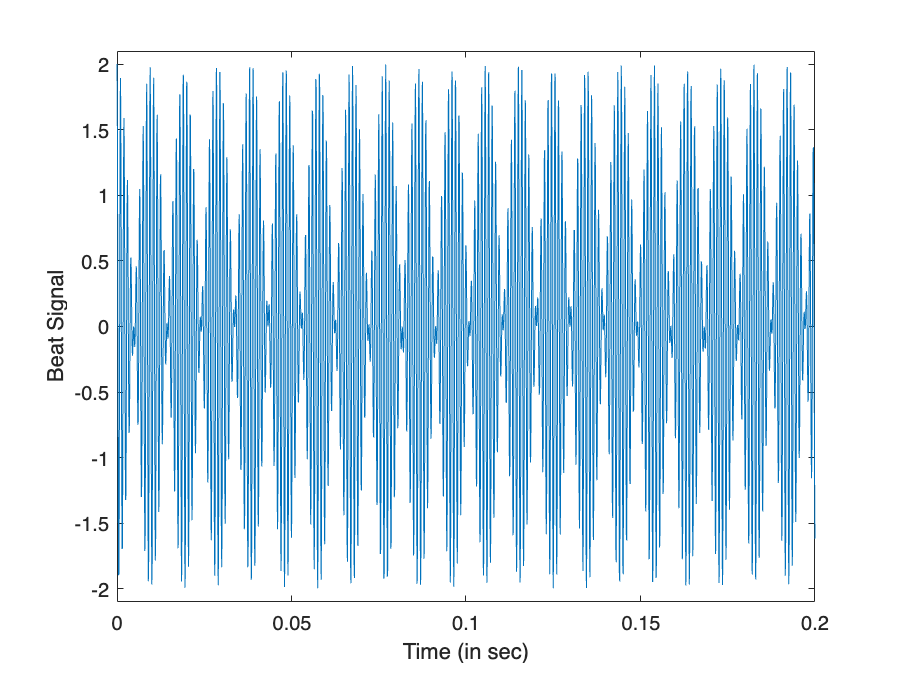

A = 1;
fc = 1000; % Hz
fa = 52; % Hz
dur = 0.42; % s
fsamp = 11025; % Hz

[xx, tt] = beat(A, fc, fa, fsamp, dur);

plot(tt,xx)
xlim([0,0.2]) % limit plot to first 0.2 seconds
ylim([-2.1*A, 2.1*A])
xlabel("Time (in sec)")
ylabel("Beat Signal")

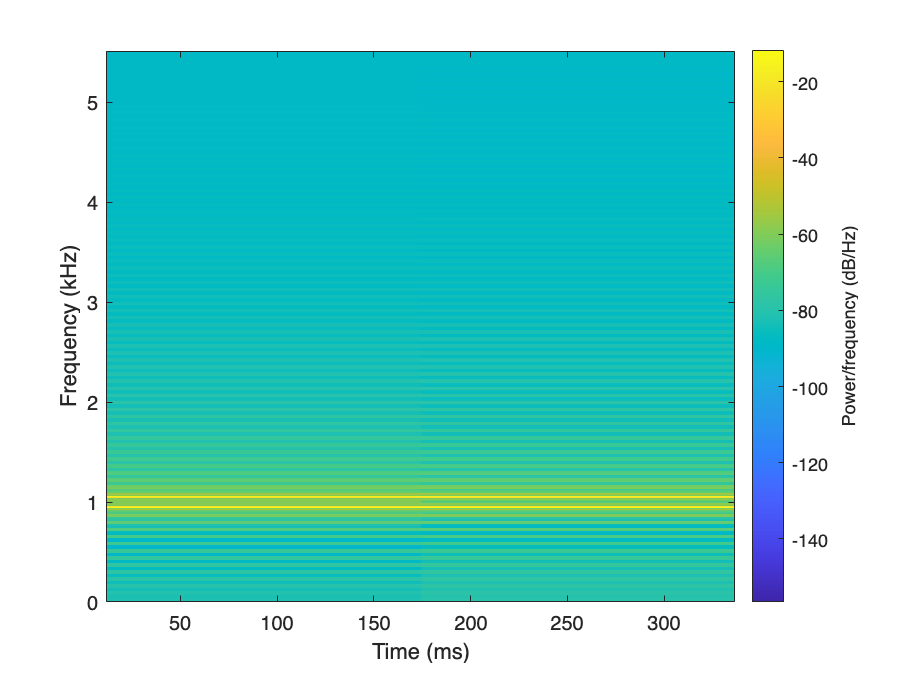


spectrogram(xx, 2048, 256, 16384, fsamp, 'yaxis')

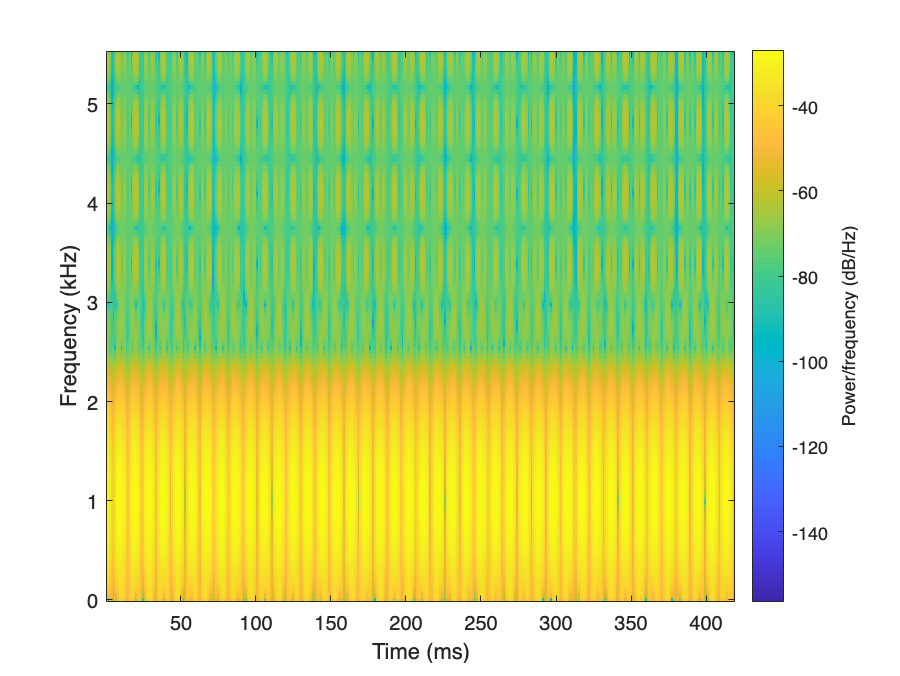


spectrogram(xx, 16, 4, 256, fsamp, 'yaxis')

**Item (3)**

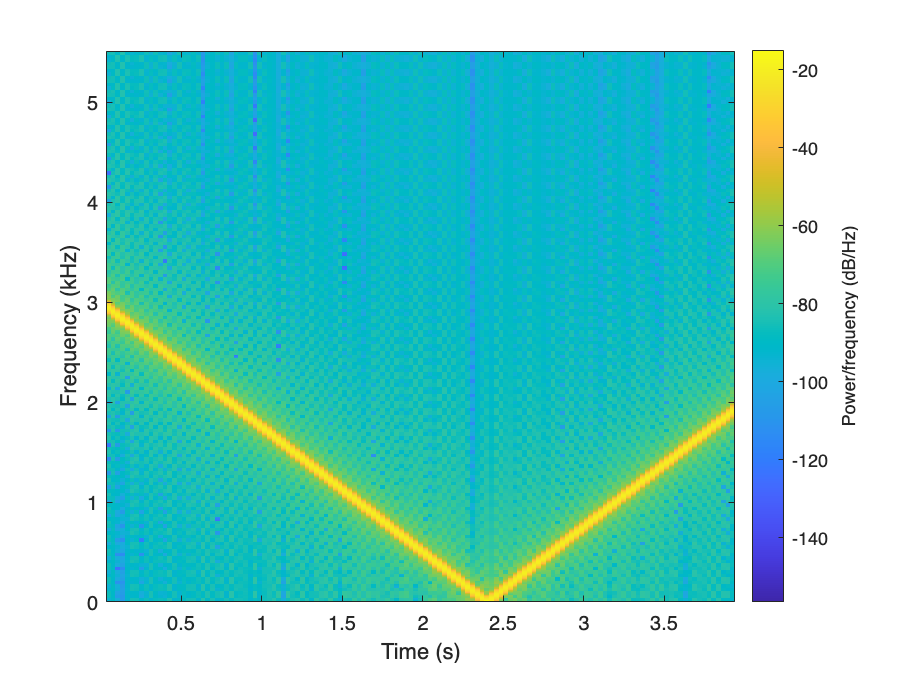

A = 1;
dur = 4; % s
f1 = 3000; % Hz
f2 = -2000; % Hz
fsamp = 11025; % Hz

[xx,tt] = mychirp(f1, f2, dur, fsamp);

soundsc(xx, fsamp);

spectrogram(xx, 1024, 700, 16384, fsamp, 'yaxis')